clear;
%% Q1 Using Matlab, normalize the input vectors, check that they are orthogonal, and construct an associative matrix that maps the following vector pairs:

s1 = [1 -1 1 -1 1 -1 1 -1]';
T1 = [0 2 2]';
s2 = [1 1 1 1 -1 -1 -1 -1]';
T2 = [-2 0 2]';
s3 = [1 1 -1 -1 1 1 -1 -1]';
T3 = [1 1 1]';

% normalize
normalized_s1 = s1/norm(s1)

normalized_s1 =     0.3536
   -0.3536
    0.3536
   -0.3536
    0.3536
   -0.3536
    0.3536
   -0.3536


normalized_s2 = s2/norm(s2)

normalized_s2 =     0.3536
    0.3536
    0.3536
    0.3536
   -0.3536
   -0.3536
   -0.3536
   -0.3536


normalized_s3 = s3/norm(s3)

normalized_s3 =     0.3536
    0.3536
   -0.3536
   -0.3536
    0.3536
    0.3536
   -0.3536
   -0.3536



% check orthogonal
normalized_s1' * normalized_s1

ans = 1.0000

normalized_s2' * normalized_s2

ans = 1.0000

normalized_s3' * normalized_s3

ans = 1.0000


% construct matrix
w1 = T1 * normalized_s1';
w2 = T2 * normalized_s2';
w3 = T3 * normalized_s3';

w = w1 + w2 + w3

w =    -0.3536   -0.3536   -1.0607   -1.0607    1.0607    1.0607    0.3536    0.3536
    1.0607   -0.3536    0.3536   -1.0607    1.0607   -0.3536    0.3536   -1.0607
    1.7678    0.3536    1.0607   -0.3536    0.3536   -1.0607   -0.3536   -1.7678




%% Q2 Use the matrix from #1, and multiply it by the average of the normalized s1 and s2.  Explain the result.

w * ((normalized_s1 + normalized_s2)/2)

ans =    -1.0000
    1.0000
    2.0000


% Explain the result: The result is the average of T1 and T2. Since w is associated with all three input pairs. A input of avg(s1 + s2) will result an output between T1 and T2


%% Q3 Generate 3 random vectors s1, s2, s3 of 100 dimensions and normalize them.  Calculate the 3 by 3 cosine matrix.  Associate the new  s1, s2, s3 with T1, T2, and T3 from exercise 1.  Construct an associative matrix and compare the responses R1, R2, R3 to the target vectors.  Repeat for 10000 dimensions.

% construct an associative matrix with three random 100 dimensions vectors
construct_matrix_of_rand_dimension(100)

cosine_v =     1.0000   -0.1862   -0.0944
   -0.1862    1.0000   -0.1214
   -0.0944   -0.1214    1.0000


T1 =      0
     2
     2


R1 =     0.2781
    1.9056
    1.5331


T2 =     -2
     0
     2


R2 =    -2.1214
   -0.4939
    1.5061


T3 =      1
     1
     1


R3 =     1.2429
    0.8113
    0.5684



% above but for 10000 dimensions
construct_matrix_of_rand_dimension(10000);

cosine_v =     1.0000   -0.0128   -0.0216
   -0.0128    1.0000   -0.0067
   -0.0216   -0.0067    1.0000


T1 =      0
     2
     2


R1 =     0.0040
    1.9784
    1.9528


T2 =     -2
     0
     2


R2 =    -2.0067
   -0.0323
    1.9677


T3 =      1
     1
     1


R3 =     1.0134
    0.9568
    0.9434


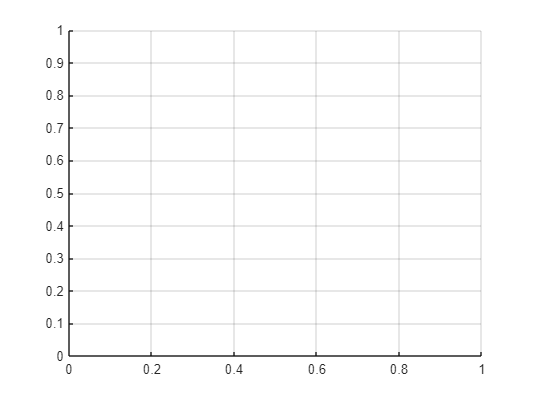


grid on

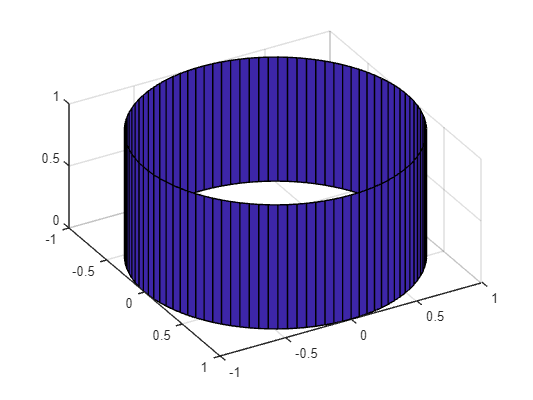

%% Q4 Create a surface plot of a cylinder (like the one below) in Matlab.  Show your Matlab commands.
figure
a=linspace(0,2*pi);
x=[cos(a); cos(a)];
y=[sin(a); sin(a)];
z=[zeros(size(a)); ones(size(a))];
surf(x,y,z);
view(60,50);

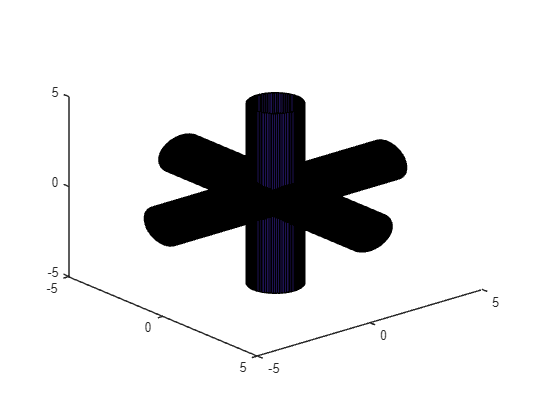


%% Q5 Create 3 cylinders on one plot as in the figure below.  Show the Matlab code.
figure
z_c=[ones(size(a))*-5; ones(size(a))*5];
hold on
surf(x,y,z_c);
surf(z_c,x,y);
surf(y,z_c,x);
hold off
view(50,30);



%% Q3 attachment

function [] = construct_matrix_of_rand_dimension(d)
% create three normalized random d dimensions vectors
s1_D100 = normc(rand(d,1)-0.5);
s2_D100 = normc(rand(d,1)-0.5);
s3_D100 = normc(rand(d,1)-0.5);

% calculate the 3 by 3 cosine matrix
s_D100 = [s1_D100 s2_D100 s3_D100];
cosine_v = s_D100' * s_D100

% associate input with target to obtain weight matrix
T1 = [0 2 2]';
T2 = [-2 0 2]';
T3 = [1 1 1]';

w1_D100 = T1 * s1_D100';
w2_D100 = T2 * s2_D100';
w3_D100 = T3 * s3_D100';

w_D100 = w1_D100 + w2_D100 + w3_D100;

% compare the responses to the target vectors
T1
R1 = w_D100*s1_D100
T2
R2 = w_D100*s2_D100
T3
R3 = w_D100*s3_D100
end
